syms x
f = (x-0.8)*(x-0.7) + 0.01

$$f = \left(x-\frac{4}{5}\right)\,\left(x-\frac{7}{10}\right)+\frac{1}{100}$$

x=solve(f,x)

$$x = \left(\begin{array}{c} \frac{3}{4}-\frac{\sqrt{3}\,\mathrm{i}}{20}\\ \frac{3}{4}+\frac{\sqrt{3}\,\mathrm{i}}{20} \end{array}\right)$$

ar={[0.8 -0.1;-0.1 0.7]}

ar = 1×1 cell array
    {2×2 double}


sigma=[9 2;2 4]

sigma =      9     2
     2     4


c=[0;0]

c =      0
     0


Mdl=varm('constant',c,'AR',ar,'Covariance',sigma)

Mdl =   varm with properties:

     Description: "AR-Stationary 2-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2" 
       NumSeries: 2
               P: 1
        Constant: [2×1 vector of zeros]
              AR: {2×2 matrix} at lag [1]
           Trend: [2×1 vector of zeros]
            Beta: [2×0 matrix]
      Covariance: [2×2 matrix]

response=irf(Mdl)

response = response(:,:,1) =

    3.0000         0
    2.3333   -0.1886
    1.8500   -0.2828
    1.4917   -0.3206
    1.2200   -0.3253
    1.0096   -0.3116
    0.8434   -0.2885
    0.7098   -0.2614
    0.6008   -0.2334
    0.5109   -0.2063
    0.4358   -0.1811
    0.3728   -0.1582
    0.3195   -0.1377
    0.2742   -0.1195
    0.2355   -0.1036
    0.2025   -0.0896
    0.1742   -0.0774
    0.1500   -0.0669
    0.1291   -0.0577
    0.1112   -0.0498


response(:,:,2) =

    0.6667    1.8856
    0.1667    1.3199
   -0.1167    0.9428
   -0.2667    0.6883
   -0.3358    0.5138
   -0.3571    0.3922
   -0.3509    0.3057
   -0.3300    0.2428
   -0.3020    0.1961
   -0.2715    0.1606
   -0.2411    0.1331
   -0.2124    0.1113
   -0.1859    0.0937
   -0.1621    0.0794
   -0.1409    0.0675
   -0.1222    0.0576
   -0.1058    0.0493
   -0.0915    0.0422
   -0.0790    0.0363
   -0.0682    0.0312


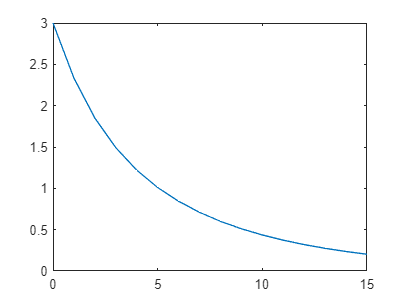


plot(0:15,response(1:16,1,1))

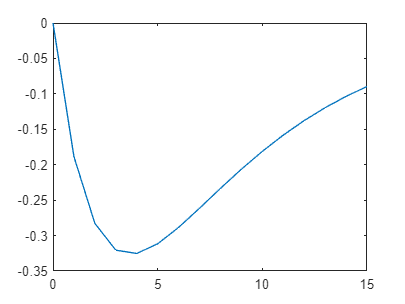


plot(0:15,response(1:16,2,1))

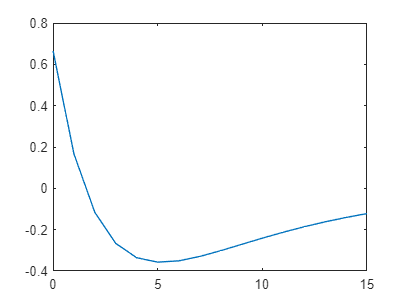


plot(0:15,response(1:16,1,2))


plot(0:15,response(1:16,2,2))

A=[3 0;2/3 4/3*sqrt(2)]

A =     3.0000         0
    0.6667    1.8856


a1=A(:,1)

a1 =     3.0000
    0.6667


a2=A(:,2)

a2 =          0
    1.8856



B=[0.8 -0.1;-0.1 0.7]

B =     0.8000   -0.1000
   -0.1000    0.7000



impulseresponse=zeros(2,16)

impulseresponse =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


A=eye(2)

A =      1     0
     0     1



for i=1:16
    impulseresponse(:,i)=A*a1
    A=B*A
end

impulseresponse =     3.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6667         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


A =     0.8000   -0.1000
   -0.1000    0.7000


impulseresponse =     3.0000    2.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6667    0.1667         0         0         0         0         0         0         0         0         0         0         0         0         0         0


A =     0.6500   -0.1500
   -0.1500    0.5000


impulseresponse =     3.0000    2.3333    1.8500         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6667    0.1667   -0.1167         0         0         0         0         0         0         0         0         0         0         0         0         0


A =     0.5350   -0.1700
   -0.1700    0.3650


impulseresponse =     3.0000    2.3333    1.8500    1.4917         0         0         0         0         0         0         0         0         0         0         0         0
    0.6667    0.1667   -0.1167   -0.2667         0         0         0         0         0         0         0         0         0         0         0         0


A =     0.4450   -0.1725
   -0.1725    0.2725


impulseresponse =     3.0000    2.3333    1.8500    1.4917    1.2200         0         0         0         0         0         0         0         0         0         0         0
    0.6667    0.1667   -0.1167   -0.2667   -0.3358         0         0         0         0         0         0         0         0         0         0         0


A =     0.3733   -0.1653
   -0.1653    0.2080


impulseresponse =     3.0000    2.3333    1.8500    1.4917    1.2200    1.0096         0         0         0         0         0         0         0         0         0         0
    0.6667    0.1667   -0.1167   -0.2667   -0.3358   -0.3571         0         0         0         0         0         0         0         0         0         0


A =     0.3151   -0.1530
   -0.1530    0.1621


impulseresponse =     3.0000    2.3333    1.8500    1.4917    1.2200    1.0096    0.8434         0         0         0         0         0         0         0         0         0
    0.6667    0.1667   -0.1167   -0.2667   -0.3358   -0.3571   -0.3509         0         0         0         0         0         0         0         0         0


A =     0.2674   -0.1386
   -0.1386    0.1288


impulseresponse =     3.0000    2.3333    1.8500    1.4917    1.2200    1.0096    0.8434    0.7098         0         0         0         0         0         0         0         0
    0.6667    0.1667   -0.1167   -0.2667   -0.3358   -0.3571   -0.3509   -0.3300         0         0         0         0         0         0         0         0


A =     0.2278   -0.1238
   -0.1238    0.1040


impulseresponse =     3.0000    2.3333    1.8500    1.4917    1.2200    1.0096    0.8434    0.7098    0.6008         0         0         0         0         0         0         0
    0.6667    0.1667   -0.1167   -0.2667   -0.3358   -0.3571   -0.3509   -0.3300   -0.3020         0         0         0         0         0         0         0


A =     0.1946   -0.1094
   -0.1094    0.0852


impulseresponse =     3.0000    2.3333    1.8500    1.4917    1.2200    1.0096    0.8434    0.7098    0.6008    0.5109         0         0         0         0         0         0
    0.6667    0.1667   -0.1167   -0.2667   -0.3358   -0.3571   -0.3509   -0.3300   -0.3020   -0.2715         0         0         0         0         0         0


A =     0.1666   -0.0961
   -0.0961    0.0706


impulseresponse =     3.0000    2.3333    1.8500    1.4917    1.2200    1.0096    0.8434    0.7098    0.6008    0.5109    0.4358         0         0         0         0         0
    0.6667    0.1667   -0.1167   -0.2667   -0.3358   -0.3571   -0.3509   -0.3300   -0.3020   -0.2715   -0.2411         0         0         0         0         0


A =     0.1429   -0.0839
   -0.0839    0.0590


impulseresponse =     3.0000    2.3333    1.8500    1.4917    1.2200    1.0096    0.8434    0.7098    0.6008    0.5109    0.4358    0.3728         0         0         0         0
    0.6667    0.1667   -0.1167   -0.2667   -0.3358   -0.3571   -0.3509   -0.3300   -0.3020   -0.2715   -0.2411   -0.2124         0         0         0         0


A =     0.1227   -0.0730
   -0.0730    0.0497


impulseresponse =     3.0000    2.3333    1.8500    1.4917    1.2200    1.0096    0.8434    0.7098    0.6008    0.5109    0.4358    0.3728    0.3195         0         0         0
    0.6667    0.1667   -0.1167   -0.2667   -0.3358   -0.3571   -0.3509   -0.3300   -0.3020   -0.2715   -0.2411   -0.2124   -0.1859         0         0         0


A =     0.1055   -0.0634
   -0.0634    0.0421


impulseresponse =     3.0000    2.3333    1.8500    1.4917    1.2200    1.0096    0.8434    0.7098    0.6008    0.5109    0.4358    0.3728    0.3195    0.2742         0         0
    0.6667    0.1667   -0.1167   -0.2667   -0.3358   -0.3571   -0.3509   -0.3300   -0.3020   -0.2715   -0.2411   -0.2124   -0.1859   -0.1621         0         0


A =     0.0907   -0.0549
   -0.0549    0.0358


impulseresponse =     3.0000    2.3333    1.8500    1.4917    1.2200    1.0096    0.8434    0.7098    0.6008    0.5109    0.4358    0.3728    0.3195    0.2742    0.2355         0
    0.6667    0.1667   -0.1167   -0.2667   -0.3358   -0.3571   -0.3509   -0.3300   -0.3020   -0.2715   -0.2411   -0.2124   -0.1859   -0.1621   -0.1409         0


A =     0.0781   -0.0475
   -0.0475    0.0306


impulseresponse =     3.0000    2.3333    1.8500    1.4917    1.2200    1.0096    0.8434    0.7098    0.6008    0.5109    0.4358    0.3728    0.3195    0.2742    0.2355    0.2025
    0.6667    0.1667   -0.1167   -0.2667   -0.3358   -0.3571   -0.3509   -0.3300   -0.3020   -0.2715   -0.2411   -0.2124   -0.1859   -0.1621   -0.1409   -0.1222


A =     0.0672   -0.0411
   -0.0411    0.0261


plot(0:15,impulseresponse(1,:))

plot(0:15,impulseresponse(2,:))



impulseresponse=zeros(2,16)

impulseresponse =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


A=eye(2)

A =      1     0
     0     1



for i=1:16
    impulseresponse(:,i)=A*a2
    A=B*A
end

impulseresponse =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.8856         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


A =     0.8000   -0.1000
   -0.1000    0.7000


impulseresponse =          0   -0.1886         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.8856    1.3199         0         0         0         0         0         0         0         0         0         0         0         0         0         0


A =     0.6500   -0.1500
   -0.1500    0.5000


impulseresponse =          0   -0.1886   -0.2828         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.8856    1.3199    0.9428         0         0         0         0         0         0         0         0         0         0         0         0         0


A =     0.5350   -0.1700
   -0.1700    0.3650


impulseresponse =          0   -0.1886   -0.2828   -0.3206         0         0         0         0         0         0         0         0         0         0         0         0
    1.8856    1.3199    0.9428    0.6883         0         0         0         0         0         0         0         0         0         0         0         0


A =     0.4450   -0.1725
   -0.1725    0.2725


impulseresponse =          0   -0.1886   -0.2828   -0.3206   -0.3253         0         0         0         0         0         0         0         0         0         0         0
    1.8856    1.3199    0.9428    0.6883    0.5138         0         0         0         0         0         0         0         0         0         0         0


A =     0.3733   -0.1653
   -0.1653    0.2080


impulseresponse = 2×16
         0   -0.1886   -0.2828   -0.3206   -0.3253   -0.3116         0         0         0         0         0         0         0         0         0         0
    1.8856    1.3199    0.9428    0.6883    0.5138    0.3922         0         0         0         0         0         0         0         0         0         0


A = 2×2
    0.3151   -0.1530
   -0.1530    0.1621


impulseresponse = 2×16
         0   -0.1886   -0.2828   -0.3206   -0.3253   -0.3116   -0.2885         0         0         0         0         0         0         0         0         0
    1.8856    1.3199    0.9428    0.6883    0.5138    0.3922    0.3057         0         0         0         0         0         0         0         0         0


A = 2×2
    0.2674   -0.1386
   -0.1386    0.1288


impulseresponse = 2×16
         0   -0.1886   -0.2828   -0.3206   -0.3253   -0.3116   -0.2885   -0.2614         0         0         0         0         0         0         0         0
    1.8856    1.3199    0.9428    0.6883    0.5138    0.3922    0.3057    0.2428         0         0         0         0         0         0         0         0


A = 2×2
    0.2278   -0.1238
   -0.1238    0.1040


impulseresponse = 2×16
         0   -0.1886   -0.2828   -0.3206   -0.3253   -0.3116   -0.2885   -0.2614   -0.2334         0         0         0         0         0         0         0
    1.8856    1.3199    0.9428    0.6883    0.5138    0.3922    0.3057    0.2428    0.1961         0         0         0         0         0         0         0


A = 2×2
    0.1946   -0.1094
   -0.1094    0.0852


impulseresponse = 2×16
         0   -0.1886   -0.2828   -0.3206   -0.3253   -0.3116   -0.2885   -0.2614   -0.2334   -0.2063         0         0         0         0         0         0
    1.8856    1.3199    0.9428    0.6883    0.5138    0.3922    0.3057    0.2428    0.1961    0.1606         0         0         0         0         0         0


A = 2×2
    0.1666   -0.0961
   -0.0961    0.0706


impulseresponse = 2×16
         0   -0.1886   -0.2828   -0.3206   -0.3253   -0.3116   -0.2885   -0.2614   -0.2334   -0.2063   -0.1811         0         0         0         0         0
    1.8856    1.3199    0.9428    0.6883    0.5138    0.3922    0.3057    0.2428    0.1961    0.1606    0.1331         0         0         0         0         0


A = 2×2
    0.1429   -0.0839
   -0.0839    0.0590


impulseresponse = 2×16
         0   -0.1886   -0.2828   -0.3206   -0.3253   -0.3116   -0.2885   -0.2614   -0.2334   -0.2063   -0.1811   -0.1582         0         0         0         0
    1.8856    1.3199    0.9428    0.6883    0.5138    0.3922    0.3057    0.2428    0.1961    0.1606    0.1331    0.1113         0         0         0         0


A = 2×2
    0.1227   -0.0730
   -0.0730    0.0497


impulseresponse = 2×16
         0   -0.1886   -0.2828   -0.3206   -0.3253   -0.3116   -0.2885   -0.2614   -0.2334   -0.2063   -0.1811   -0.1582   -0.1377         0         0         0
    1.8856    1.3199    0.9428    0.6883    0.5138    0.3922    0.3057    0.2428    0.1961    0.1606    0.1331    0.1113    0.0937         0         0         0


A = 2×2
    0.1055   -0.0634
   -0.0634    0.0421


impulseresponse = 2×16
         0   -0.1886   -0.2828   -0.3206   -0.3253   -0.3116   -0.2885   -0.2614   -0.2334   -0.2063   -0.1811   -0.1582   -0.1377   -0.1195         0         0
    1.8856    1.3199    0.9428    0.6883    0.5138    0.3922    0.3057    0.2428    0.1961    0.1606    0.1331    0.1113    0.0937    0.0794         0         0


A = 2×2
    0.0907   -0.0549
   -0.0549    0.0358


impulseresponse = 2×16
         0   -0.1886   -0.2828   -0.3206   -0.3253   -0.3116   -0.2885   -0.2614   -0.2334   -0.2063   -0.1811   -0.1582   -0.1377   -0.1195   -0.1036         0
    1.8856    1.3199    0.9428    0.6883    0.5138    0.3922    0.3057    0.2428    0.1961    0.1606    0.1331    0.1113    0.0937    0.0794    0.0675         0


A = 2×2
    0.0781   -0.0475
   -0.0475    0.0306


impulseresponse = 2×16
         0   -0.1886   -0.2828   -0.3206   -0.3253   -0.3116   -0.2885   -0.2614   -0.2334   -0.2063   -0.1811   -0.1582   -0.1377   -0.1195   -0.1036   -0.0896
    1.8856    1.3199    0.9428    0.6883    0.5138    0.3922    0.3057    0.2428    0.1961    0.1606    0.1331    0.1113    0.0937    0.0794    0.0675    0.0576


A = 2×2
    0.0672   -0.0411
   -0.0411    0.0261


plot(0:15,impulseresponse(1,:))

plot(0:15,impulseresponse(2,:))